# Week 2 Homework

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

The three problem statements are given as:

### **Problem Statement II-1:**

Find Problem 2-13 in the Spong et al.

- Write the matrix product that will give the resulting rotation matrix.

- Program in Matlab code and put comments that represent the sequence of rotations from 1-4.

- Produce a random number for all angle variables, and derive the matrix product with numeric values in it..

### **Problem Statement II-2:**

Find Problem 2-38 in the in the Spong et al.

- Write the homogeneous matrices for all three H's.

- Program in Matlab code and derive H23 in numeric values.

### **Problem Statement II-3:**

1. Study the Denso's HSR robot.

[Here (Links to an external site.)](https://www.densorobotics.com/products/4-axis/hsr-series/) is the link to the product page and video. 

2. Open the product specification in the [LINK.     (Links to an external site.)](https://www.densorobotics.com/products/4-axis/hsr-series/)Download a [catalog (Links to an external site.)](https://api.densorobotics.com/downloads/file/4).  Consider 480 mm reach model with 100 mm z-stroke . 

3. Discuss the homogeneous coordinate transformation from the base to the tip of the end third link (z-axis). Ignore the fourth rotational motion. Define the coordinate system of the base, and the links as you wish. Define any variables as you wish. (In a few weeks, I will define the rules of variables definitions. So enjoy your freedom to define your coordinate system as you wish. Try to use the same notations (H, sub and superscript, theta, phi etc) we used in the lecture though  )

4. Program the the homogeneous coordinate transformation above in Matlab.

5. Rotate the first axis near the base 0 to 180 degrees clock wise (looking from above) from the initial Configuration Space with 1 degree interval. At the same time, rotate the second axis from the base 0 to 90 degrees clock wise (looking from above) from the initial Configuration Space with 0.5 degree interval.  At the same time, give z-axis a stroke ranging from 0 to 100 mm with 100/180 mm interval. Plot the tip of the third z-axis in Matlab.

### Approach:

Each of these stated problems requires its own individual approach. The approaches are summarized in the below subsections.

#### Problem Statement II-1:

Problem 2-13 in Spong et al. wants the reader to consider the following sequence of rotations and write the resulting matrix product that yields these rotations:  

- Rotate by ϕ about the world x-axis. 

- Rotate by θ about the world z-axis.

- Rotate by ψ about the current x-axis. 

- Rotate by α about the world z-axis. 

The approach taken is to build up a composite rotation matrix by pre-multiplying and post-multiplying the composite matrix in order to rotate either about a world axis fixed frame or current axis in the appropriate multiplicative order. 

#### Problem Statement II-2:

Problem 2-38 in Spong et al. wants the reader to consider Figure 2.14, which consists of a robot, a table, a cube placed at the center of the table and a camera affixed to the ceiling of the room. All of the distance relationships and coordinate frame locations are given in the figure. 

The approact taken is to determine the homogeneous matricies that relate each coordinate frames in a successive manner. From these relationships, any relation between coordinate frames (including any frame's relationship to the base or "world" frame) can be deduced. Finally, the relationship between frame 2 and frame 3,$H_3^2 \;$, can be evaluated numerically and described as requested. 

#### Problem Statement II-3:

This problem statement first requires the identification of the appropriate Denso robot model and associated specification information. Once this information is obtained, a simplified model of the robot will be created with variables such as linkage and joints defined. From this, relevant coordinate frames can be described, as can the homogeneous matricies that define the relationship between the frames. The resulting model for the system is programmed into MATLAB as a series of homogeneous matrix transformation. Finally, the model is made to step through the described rotations and translations and the position of the tip of the end effector of the robot is plotted for each step. 

## Materials and Methods:

### Problem Statement II-1:

The general form of a rotation matrix is based upon the trigonometric relationships between a vector and its relation to the coordinate frame in which it resides. Consider the figure below from Spong et al. that depicts two coordinate frames $o_0 x_0 y_0$ and $o_1 x_1 y_1$ :

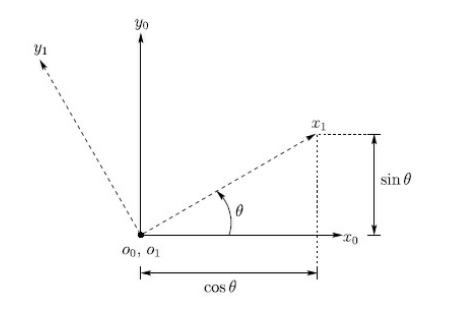

The x- and y-coordinates of $x_1$and $y_1$ within the $o_0 x_0 y_0$ frame can be descibed in terms of the cosine and sine relationships that relate $o_1 x_1 y_1$ to $o_0 x_0 y_0$ such that, when these coordinates are descibed as column vectors of a 2x2 matrix, the following r**otation matrix **is obtained with the first and second columns described $x_1$ and $y_1$, respectively, in the base frame $o_0 x_0 y_0$,


$$R_1^0 =\left\lbrack \begin{array}{cc}
\cos \;\theta  & -\sin \;\theta \\
\sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack$$


In essence, a rotation matrix relates two coordinate frames. The above 2x2 matrix relates coordinate frame 1 (as indicated by the subscript) to coordinate frame 0 (as indicated by the superscript). 

This type of relationship scales neatly to the 3-dimensional case. To rotate a frame about an axis, it is simply a matter of holding the axis of rotation constant and rotating the other two axes by some angle. The z-axis, y-axis and x-axis rotation matricies are given below. 


$$R_{z,\theta } \left\lbrack \begin{array}{ccc}
\cos \;\theta  & -\sin \;\theta  & 0\\
\sin \;\theta  & \cos \;\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_{y,\theta } \left\lbrack \begin{array}{ccc}
\cos \;\theta  & 0 & \sin \;\theta \\
0 & 1 & 0\\
-\sin \;\theta  & 0 & \cos \;\theta 
\end{array}\right\rbrack$$



$$R_{x,\theta } \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \;\theta  & -\sin \;\theta \\
0 & \sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack$$


Note that by convention these rotations are **counterclockwise** by the right hand rule.

Composite rotation matricies can be built up by multiplying together the single-axis rotation matricies above. As Spong et al. explains, given a fixed frame $o_0 x_0 y_0 z_0$ and a current frame $o_1 x_1 y_1 z_1$ together with a rotation matrix $R_1^0$ relating them, if a third frame $o_2 x_2 y_2 z_2$ is obtained by a rotation $R$ performed relative to the **current** frame then the rotation matrix $R_1^0$ can be post-multiplied by $R=R_2^1$ to relate the base frame $o_0 x_0 y_0 z_0$ to $o_2 x_2 y_2 z_2$ such that 


$$R_2^0 =R_1^0 R_2^1$$


However, if the rotation $R$ as described above is to be performed relative to the **world or fixed frame **$o_0 x_0 y_0 z_0$, then the first rotation $R_1^0$ can be pre-multiplied by $R$ to rotate the current rotation matrix about the fixed frame:


$$R_2^0 ={\textrm{RR}}_1^0$$


With this in mind, it is possible to pre- or post-multiply the current rotation matrix by each successive rotation matrix to yield a composite rotation matrix that realizes rotations requested in Problem Statement II-1. 

Building up the composite rotation matrix $R$ by multiplication requested in Problem Statement II-1 requires these steps:

- $R=R_{x\phi }$ (rotation about the world x-axis)

- $R=R_{z\theta } R_{x\phi }$ (pre-multiply by $R_{z\theta }$ for rotation about the world z-axis)

- $R=R_{z\theta } R_{x\phi } R_{x\psi }$(post-multiply by $R_{x\psi }$ for rotation about the current x-axis) 

- $R=R_{z\alpha } R_{z\theta } R_{x\phi } R_{x\psi }$(pre-multiply by $R_{z\alpha }$ for rotation about the world z-axis)

The resulting matrix product is:


$$R=R_{z\alpha } R_{z\theta } R_{x\phi } R_{x\psi }$$


This is easily realized in MATLAB by defining each matrix symbolically with help from the `syms` command:

syms phi theta psi alpha

%rotations in multiplicative order
R_zalpha = [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1] %first rotation

$$R\_zalpha = \left(\begin{array}{ccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_ztheta = [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1] %second rotation

$$R\_ztheta = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_xphi = [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi)] %third rotation

$$R\_xphi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

R_xpsi = [1 0 0; 0 cos(psi) -sin(psi); 0 sin(psi) cos(psi)] %fourth rotation

$$R\_xpsi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & -\sin\left(\psi \right)\\ 0 & \sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

The composite rotation matrix can now be represented by the multiplication of each matrix in order:

R_composite= R_zalpha * R_ztheta * R_xphi * R_xpsi

$$R\_composite = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{3}-\sigma_{2} & \sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sigma_{1}-\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sigma_{1} & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sigma_{1}+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sigma_{1}\\ \sigma_{1} & \sin\left(\varphi \right)\,\sin\left(\psi \right)\,\left(\sigma_{2}-\sigma_{3}\right)-\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\left(\sigma_{2}-\sigma_{3}\right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\left(\sigma_{2}-\sigma_{3}\right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\left(\sigma_{2}-\sigma_{3}\right)\\ 0 & \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\alpha \right)\,\sin\left(\theta \right)+\sin\left(\alpha \right)\,\cos\left(\theta \right)\\ \sigma_{2}=\sin\left(\alpha \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\cos\left(\alpha \right)\,\cos\left(\theta \right) \end{array}$$

### Problem Statement II-2:

A **rigid motion **combines the matrix transformations that result in translation and rotation. Suppose the point $p^1$ is rigidly attached to coordinate frame $o_1 x_1 y_1 z_1$, with local coordinates . We can express the coordinates of $p^1$ with respect to frame $o_0 x_0 y_0 z_0 \;$using:


$$p^0 =R_1^0 p^1 +d^0$$


where $d^0$ is a translation matrix. If a third coordinate frame $o_2 x_2 y_2 z_2$ is considered and point $p\;$is defined now with respect to this frame, its coordinates relative to the world frame $o_0 x_0 y_0 z_0$ are:


$$p^1 =R_2^1 p^2 +d_2^1$$


and


$$p^0 =R_1^0 p^1 +d_1^0$$


with the combination of these two equations yielding 


$$p^0 =R_1^0 {R_2^1 p}^2 +R_1^0 {d_2^1 +d}_1^0$$


**Homogeneous transfomations** can be used to express this relationship much more concisely. The homogeneous transformation takes the form:


$$H=\left\lbrack \begin{array}{cc}
R & d\\
0 & 1
\end{array}\right\rbrack ,\;R\in \;\mathrm{SO}\left(3\right),\;d\in \Re^3$$
 

Continuing the discussion of representing points in three dimensions as noted above, a homogeneous transformation is realized by a 4x4 matrix where the first three columns are a rotation matrix and the last column is a translation vector: $H=\left\lbrack \begin{array}{cccc}
n_x  & s_x  & a_x  & d_x \\
n_y  & s_y  & a_y  & d_y \\
n_z  & s_z  & a_z  & d_z \\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
n & s & a & d\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

where $n,s,a\;\textrm{and}\;d$ are vectors representing the direction of $x_1 ,\;y_1 \;\textrm{and}\;z_1$ in the $o_0 x_0 y_0 z_0$ coordinate system. The $d$ vector represents the vector from the origin of coordinate frame 0 to coordinate frame 1 as expressed in coordinate frame 0.

The same rules for composing and ordering composite rotation matricies hold for homogeneous transforms. That is to say that if given a transformation $H_1^0$ relating frames 0 and 1, if a further second rigid motion $H$ is to be performed relative to the current frame, then 


$$H_2^0 =H_1^0 H$$


and if $H$ is to be performed relative to the world or fixed frame then


$$H_2^0 ={\mathrm{HH}}_1^0$$


To apply the transformation descibed by a homogeneous transform to a point, a 4th component of 1 is appended to the point vector $p$ as shown in order to make matrix-vector multiplication possible:

$p=\left\lbrack \begin{array}{c}
p\\
1
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
p_x \\
p_y \\
p_z \\
1
\end{array}\right\rbrack$

This augumented point vector is known as the **homogeneous represention** of the vector $p$.

Given this background, we are able to express the coordinate frames in Problem Statement II-2, problem 2-38 as composites of homogeneous transforms that can be ultimately related to the world frame. Given the figure:

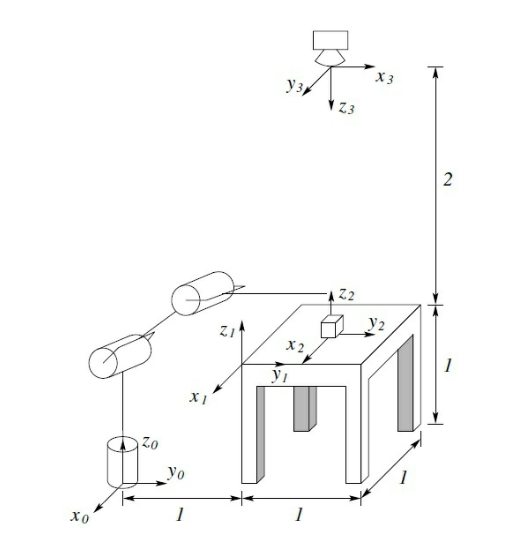

and the problem description,

*Consider the diagram of Figure 2.14. A robot is set up 1 meter from a table. The table top is 1 meter high and 1 meter square. A frame o1x1y1z1 is fixed to the edge of the table as shown. A cube measuring 20 cm on a side is placed in the center of the table with frame o2x2y2z2 established at the center of the cube as shown. A camera is situated directly above the center of the block 2 meters above the table top with frame o3x3y3z3 attached as shown. Find the homogeneous transformations relating each of these frames to the base frame o0x0y0z0. Find the homogeneous transformation relating the frame o2x2y2z2 to the camera frame o3x3y3z3*.

we can express each of the coordinate frames from 0 to 3 in terms of successive homogeneous transforms as we are given their dimensional relationships to one another.

First, $H_1^0$ can be written as a translation from frame 0 to frame 1 by 1m in y and 1m in z. There is no rotational component needed.


$$H_1^0 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 1\\
0 & 0 & 1 & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Second $H_2^1$ can be written as a translation from frame 1 to frame 2 by -0.5m in x, 0.5m in y and 0.1m (10cm) in z to place coordinate frame 2 at the center of the cube on the table.


$$H_2^1 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & -0\ldotp 5\\
0 & 1 & 0 & 0\ldotp 5\\
0 & 0 & 1 & 0\ldotp 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Third, $H_3^2$ can be written as a translation frome frame 2 to frame 3  by 1.9m in the z-direction combined with a rotation about the z-axis by 90 degrees and then about the currrent x-axis by 180 degrees.

First, the composite rotation is (n.b. cosine and sine terms are expressed here as $c\theta \;\mathrm{and}\;s\theta$, for example):

$R_{z\theta } R_{x\phi } =\left\lbrack \begin{array}{ccc}
c\theta  & -s\theta  & 0\\
s\theta  & c\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\phi  & -s\phi \\
0 & s\phi  & c\phi 
\end{array}\right\rbrack$ =$\left\lbrack \begin{array}{ccc}
c\theta  & -s\theta c\phi  & s\theta s\phi \\
s\theta  & c\theta c\phi  & -c\theta s\phi \\
0 & s\phi  & c\phi 
\end{array}\right\rbrack$

and combining this with a translation in z yields the homogeneous matrix:


$$H_3^2 =\left\lbrack \begin{array}{cccc}
c\theta  & -s\theta c\phi  & s\theta s\phi  & 0\\
s\theta  & c\theta c\phi  & -c\theta s\phi  & 0\\
0 & s\phi  & c\phi  & 1\ldotp 9\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Finally, the relationship of coordinate frame 3 to coordinate frame 0 can be expressed as a composite homogeneous transformation


$$H_3^0 =H_1^0 H_2^1 H_3^2$$


Similarly, the relationship of coordinate frame 2 to coordinate frame 0 can be expressed as a composite homogeneous transformation as well


$$H_2^0 =H_1^0 H_2^1$$


It has thus been shown that we have established relationship, by way of composite homogenous transforms) relating, relating each frame to the base frame as well as to each other in successive fashion. The symbolic and numerical solutions ot these equations can be computed with the help of MATLAB

### Problem Statement II-3:

Using the background of mathematics regarding rigid motions in $\Re^3$ described in the Materials and Methods subsections Problem Statement II-1 and Problem Statement II-2, it is possible to define coordinate frames and the homogenous matricies that relate them to one another in a way that descibes the position of the end effector of a Denso HSR series robot. 

The catalog provided in the problem statement gives these dimensional specifications for the robot. 

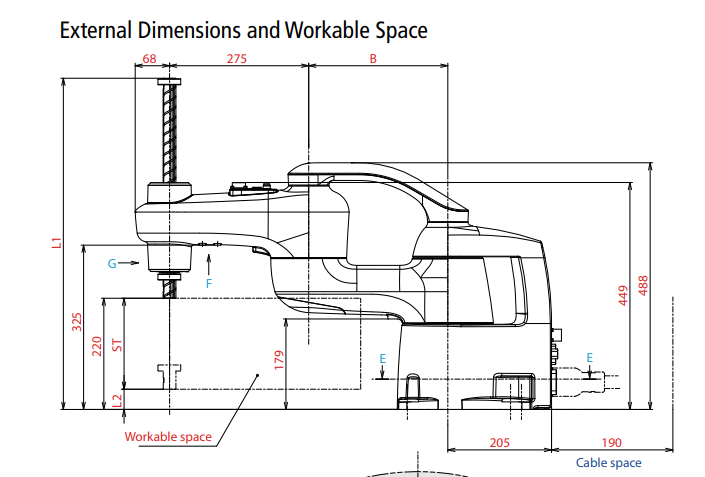

For a 480mm maximum reach robot, B in the figure above is given as 205mm.

From this, we can define 4 coordinate frames:

- $o_0 x_0 y_0 z_0$, the base frame at the center of the base of the robot where it meets the floor. 

- $o_1 x_1 y_1 z_1$, the first frame from the base frame, located at the center of the first rotational joint

- $o_2 x_2 y_2 z_2$, the seconnd frame from the base frame, located at the center of the second rotational joint

- $o_3 x_3 y_3 z_3$, the third frame from the base frame, located at the tip of the end effector whose z position is determined by the prismatic joint.

given how we defined these frames, a simplified model of the robot was created:

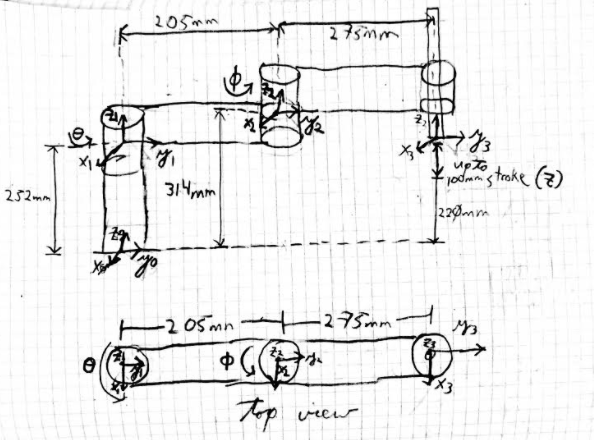

where the variables $\theta ,\phi \;\mathrm{and}\;\Delta \;$(delta shown as **z** in the drawing) representing the first joint angle, second joint angle and displacement in z or the"stroke" of the end effector, respectively. The simplified model above makes a couple of assumptions about the location of the coordinate frames based on the dimensions given for the Deno robot, chiefly:

- The center of the first joint from the base is $\frac{179+325}{2}=252\mathrm{mm}$ in z from the base

- The center of the second joint from the base is $\frac{449+179}{2}=314\mathrm{mm}$ in z from the base. 

With the dimensional relationships established in our simplified model, we can now define homogeneous matricies that relate each of the coordinate frames. 

The homogeneous transformation $H_1^0$ is a rotation about the Z-axis by $\theta$ and a translation in z by 252mm.


$$H_1^0 =\left\lbrack \begin{array}{cccc}
c\theta  & -s\theta  & 0 & 0\\
\mathrm{sin}\theta  & c\theta  & 0 & 0\\
0 & 0 & 1 & 252\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The homogeneous transformation $H_2^1$ is a rotation about the Z-axis by $\phi$ and a translation in z by 314mm - 252mm = 62mm along with a translation in y of 205mm.


$$H_2^1 =\left\lbrack \begin{array}{cccc}
c\phi  & -s\phi  & 0 & 0\\
\mathrm{sin}\phi  & c\phi  & 0 & 205\\
0 & 0 & 1 & 62\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The homogeneous transformation $H_3^2$ is a translation of 220mm - 314mm = -94mm in z and a translation in y by 275mm. To capture the change in stroke distance, the z translation term has a variable $\Delta$ subtracted from it. The resultant translation in z is -94mm - $\Delta$.


$$H_2^1 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 275\\
0 & 0 & 1 & -94-\Delta \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The resulting composite homogeneous transformation describing coordinate frame 3 (the end effector) in relation to coordinate frame 0  (the world coordinate system), $H_3^0$,  is given as:


$$H_3^0 =H_1^0 H_2^1 H_3^2$$


The symbolic and numerical solutions ot these equations can be computed with the help of MATLAB to obtain the position of coordinate frame 3 (the tip of the end effector) in the path described in Problem Statement II-3.

## Results:    

### Problem Statement II-1:

It was shown that a composite rotation matrix that describes the rotation sequence given in Problem Statement II-1 could be realized by pre- or post- multiplying the current composite rotation matrix by a rotation matrix that represents a successive rotation step.  The resulting multiplication sequence was found to be:


$$R=R_{z\alpha } R_{z\theta } R_{x\phi } R_{x\psi }$$


This matrix was computed in MATLAB in the previous section symbolically. 

To compute the rotation matrix numerically with random numbers, we make use of the built-in random number generator `rng.` We seed `rng` with a value (in this case 42) so that the random numbers are repeatable from run-to-run and specify "twister" as the random number generating method:

rng(42,"twister"); %seed random number generator for repeatability.

a = 0; %lower random value bound for rotation angles - if 0 its technically not needed 
b = 2*pi; %upper random value bound for rotation angles (radians)

r = (b-a).*rand(4,1) + a; %generate a 4x1 array of random values between 0 and 2pi
r_range = [min(r) max(r)] %confirm range is within upper and lower bounds

r_range =     2.3533    5.9735



%random rotation angle value assignment to rotation variables
phi = r(1,1) 

phi = 2.3533

theta = r(2,1)

theta = 5.9735

psi = r(3,1)

psi = 4.5993

alpha = r(4,1)

alpha = 3.7615

Here, we have defined bounds for the randomly generated rotation angles in radians. The lower bound is 0 radians while the upper bound is $2\pi \;$radians or a full rotation. Variable `r` is a 4x1 array of random values between 0 and $2\pi$. The equation defining `r` is a scale-and-offset operation to map the values of r, which range from 0 to 1, to a range from 0 to $2\pi$.

The variables from phi to alpha are then each assigned a variable from each row of r for use in the composite rotation matrix

Solving numerically consists of simply defining and computing the composite rotation matrix and its components again with the rotation angles now defined numerically rather than symbolically:

%rotations listed in multiplicative order
R_zalpha = [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1] %first rotation

R_zalpha =    -0.8139    0.5809         0
   -0.5809   -0.8139         0
         0         0    1.0000


R_ztheta = [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1] %second rotation

R_ztheta =     0.9524    0.3047         0
   -0.3047    0.9524         0
         0         0    1.0000


R_xphi = [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi)] %third rotation

R_xphi =     1.0000         0         0
         0   -0.7051   -0.7091
         0    0.7091   -0.7051


R_xpsi = [1 0 0; 0 cos(psi) -sin(psi); 0 sin(psi) cos(psi)] %fourth rotation

R_xpsi =     1.0000         0         0
         0   -0.1129    0.9936
         0   -0.9936   -0.1129



%computed composite rotation
R_composite= R_zalpha * R_ztheta * R_xphi * R_xpsi

R_composite =    -0.9523    0.2394   -0.1894
   -0.3053   -0.7468    0.5909
         0    0.6205    0.7842


### Problem Statement II-2:

It was shown that each of the coordinate frames in the figure were related to the base frame by multiplication of homogeneous matricies that describe rigid motion from one frame to anther.  

Here, we can now use MATLAB to symbolically and numerically compute these relationships as composite matricies.

First, $H_1^0$ expresses coordinate frame 1 in terms of coordinate frame 0 - it is a translation of 1m in y and 1m in z without rotation:

H01 = [1 0 0 0; 0 1 0 1; 0 0 1 1; 0 0 0 1]

H01 =      1     0     0     0
     0     1     0     1
     0     0     1     1
     0     0     0     1


Second, $H_2^1 \;$expresses coordinate frame 2 in terms of coordinate frame 1 - it is a translation of -0.5m in x, 0.5m in y and 10cm (0.1m) in z to place frame 2 at the center of the cube that is at the center of the table. 

H12 = [1 0 0 -0.5; 0 1 0 0.5; 0 0 1 0.1; 0 0 0 1]

H12 =     1.0000         0         0   -0.5000
         0    1.0000         0    0.5000
         0         0    1.0000    0.1000
         0         0         0    1.0000


Third, $H_3^2 \;\;$expresses coordinate frame 3 in terms of coordinate frame 2 - its rotational component $R=R_{z,\theta } R_{x,\psi }$ is first a rotation about z by $\theta =\frac{\pi }{2}$ (90 degrees) then a rotation about the current x frame by $\psi =\pi$ (180 degrees). Its translational component is a translation in z by 1.9m.

Symbolically, this is:

syms theta phi
H23 = [cos(theta) -sin(theta)*cos(phi) sin(theta)*sin(phi) 0; sin(theta) cos(theta)*cos(phi) -cos(theta)*sin(phi) 0; 0 sin(phi) cos(phi) 1.90; 0 0 0 1]

$$H23 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right) & 0\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) & \frac{19}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Thus the total transformation (symbolically) from frame 0 to frame 3 is:

H03 = H01 * H12 * H23

$$H03 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right) & -\frac{1}{2}\\ \sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right) & \frac{3}{2}\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) & 3\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The total transformation from frame 0 to frame 2 numerically is:

H02 = H01 * H12

H02 =     1.0000         0         0   -0.5000
         0    1.0000         0    1.5000
         0         0    1.0000    1.1000
         0         0         0    1.0000


Plugging in $\theta =\frac{\pi }{2}\;\mathrm{and}\;\phi =\pi$ (90 degrees and 180 degrees, respectively), yields the following numerically computed transformation for $H_3^2 \;$and the total transformation from frame 0 to frame 3, $H_3^0$:

theta = pi/2;
phi = pi;

%re-define H23 with numerical values and compute H03 numerically.
H23 = [cos(theta) -sin(theta)*cos(phi) sin(theta)*sin(phi) 0; sin(theta) cos(theta)*cos(phi) -cos(theta)*sin(phi) 0; 0 sin(phi) cos(phi) 1.90; 0 0 0 1]

H23 =     0.0000    1.0000    0.0000         0
    1.0000   -0.0000   -0.0000         0
         0    0.0000   -1.0000    1.9000
         0         0         0    1.0000


H03 = H01 * H12 * H23

H03 =     0.0000    1.0000    0.0000   -0.5000
    1.0000   -0.0000   -0.0000    1.5000
         0    0.0000   -1.0000    3.0000
         0         0         0    1.0000


With this, we have computed all homogeneous transform relationships between any coordinate frame and the base frame both symbolically and numerically using MATLAB and can express any point in any coordinate frame within the system described in terms of the base frame.

### Problem Statement II-3:

It was shown in the previous section that each of the coordinate frames for the Denso robot could be defined and then related to the base frame by multiplication of homogeneous matricies that describe the location of  one frame relative to another.

Here, we can now use MATLAB to symbolically and numerically compute the homeogeneous matricies with the ultimate goal of descibing the position of the end effector given by the origin of coordinate frame 3 in terms of frame 0. Finally, we can apply a stepped motion that takes the model of the Denso robot through a simultaneous 180 degree clockwise rotation on the first rotational joint, a 90 degree clockwise rotation on the second rotational joint and a 100mm downward z-stroke on the prismatic joint in 180 stepped increments each. 

First, the homogeneous  transformation $H_1^0$ is a rotation about the Z-axis by $\theta$ and a translation in z by 252mm.

syms theta

H01_denso = [cos(theta) -sin(theta) 0 0; sin(theta) cos(theta) 0 0; 0 0 1 252; 0 0 0 1]

$$H01\_denso = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0\\ 0 & 0 & 1 & 252\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The homogeneous transformation $H_2^1$ is a rotation about the Z-axis by $\phi$ and a translation in z by 314mm - 252mm = 62mm along with a translation in y of 205mm.

syms phi

H12_denso = [cos(phi) -sin(phi) 0 0; sin(phi) cos(phi) 0 205; 0 0 1 62; 0 0 0 1]

$$H12\_denso = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0 & 205\\ 0 & 0 & 1 & 62\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The homogeneous transformation $H_3^2$ is a translation of 220mm - 314mm = -94mm in z and a translation in y by 275mm. To capture the change in stroke distance, the z translation term has a variable $\Delta$ subtracted from it. The resultant translation in z is -94mm - $\Delta$.

syms Delta

H23_denso = [1 0 0 0; 0 1 0 275; 0 0 1 -94-Delta; 0 0 0 1]

$$H23\_denso = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 275\\ 0 & 0 & 1 & -\Delta -94\\ 0 & 0 & 0 & 1 \end{array}\right)$$

The resulting composite homogeneous transformation relating coordinate frame 3 (the end effector) to coordinate frame 0  (the world coordinate system), $H_3^0$,  is given as:

H03_denso = H01_denso * H12_denso * H23_denso

$$H03\_denso = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & -205\,\sin\left(\theta \right)-275\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-275\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 205\,\cos\left(\theta \right)+275\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-275\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 220-\Delta \\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\varphi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sigma_{3}=\cos\left(\varphi \right)\,\sin\left(\theta \right) \end{array}$$

To check, setting $\theta$, $\phi$ and $\Delta$ to 0 in $H_3^0$ ought to yield x=0, y = 480mm, z=220mm as drawn. Other joint/z-stroke manipulations can also be verified with the following MATLAB code as needed:

% Check individual angles /z strokes
% 
% theta = 0
% phi = 0
% Delta = 0
%  
% H01denso = [cos(theta) -sin(theta) 0 0; sin(theta) cos(theta) 0 0; 0 0 1 252; 0 0 0 1];
% H12denso = [cos(phi) -sin(phi) 0 0; sin(phi) cos(phi) 0 205; 0 0 1 62; 0 0 0 1];
% H23denso = [1 0 0 0; 0 1 0 275; 0 0 1 -94-Delta; 0 0 0 1];
% H03denso = H01denso * H12denso * H23denso
% 
% pt = [0;0;0;1];
% 
% H03denso*pt

With the homogeneous matrix transformation defined with angle and z-stroke distance variables, ranges of values for these variables can be defined to 180 evenly-stepped increments using `linspace:`

linspace_theta = linspace(0, -180, 180); %180 pts from 0 to -180deg - 1 degree increments
linspace_phi = linspace(0, -90, 180); %180 pts from 0 to -90deg - 0.5 degree increments
linspace_Delta = linspace(0, 100, 180); %180 points from 0 to 100mm in 10/18mm increments

With arrays of values for the 2 angle variables and the z-stroke distance, each end-effector step can be calculated:

%pre-allocate the array spaces in memory to speed up calc time. 
%merely a 1x180 array of all 0's
x_effector = zeros(1,180); 
y_effector= zeros(1,180);
z_effector = zeros(1,180);

%Homogeneous representation of point 0,0,0 in coord. frame 3
effector_start_pt = [0;0;0;1]; 

%step through all 180 positions of the end effector tip
for i = 1:180
    %H's are defined with numerical angles and z-stroke
    H01denso = [cos(deg2rad(linspace_theta(1,i))) -sin(deg2rad(linspace_theta(1,i))) 0 0; sin(deg2rad(linspace_theta(1,i))) cos(deg2rad(linspace_theta(1,i))) 0 0; 0 0 1 252; 0 0 0 1];
    H12denso = [cos(deg2rad(linspace_phi(1,i))) -sin(deg2rad(linspace_phi(1,i))) 0 0; sin(deg2rad(linspace_phi(1,i))) cos(deg2rad(linspace_phi(1,i))) 0 205; 0 0 1 62; 0 0 0 1];
    H23denso = [1 0 0 0; 0 1 0 275; 0 0 1 -94-linspace_Delta(1,i); 0 0 0 1];
    
    %create composite H
    H03denso = H01denso * H12denso * H23denso; 
    
    %apply transformation to effector start pt
    transformed_pt = H03denso*effector_start_pt;
    
    %add x,y,z coordinates w.r.t. base frame to x,y,z coordinate-holding arrays
    x_effector(1,i) = transformed_pt(1,1);
    y_effector(1,i) = transformed_pt(2,1);
    z_effector(1,i) = transformed_pt(3,1);
    
end

Here, we first define a start point for the end effector as [0,0,0] in coordinate frame 3. Then, we define for loop that loops 180 times. For each loop, a new successive ith value from the `linspace`'s defining the steps for $\theta ,\phi \;\mathrm{and}\;\Delta \;$ is passed into the equations for each of the component homogeneous matricies that descibe the Denso robot system. `deg2rad` is a built-in function that converts the degree value held in the `linspace` arrays that hold angle values to a radian value that can be passed to the `cos` and `sin` functions. The computed H's are then multiplied together to express coordinate frame 3 in terms of the base coordinate frame and the resulting $H_3^0$ is multiplied with the effector start point to obtain point as expressed in terms of the base frame. Finally, the x, y and z components of this `transformed_pt` are passed into the ith column of the `x_effector, y_effector `and` z_effector` arrays for ease of plotting.

Plotting the x,y and z end effector coordinate arrays yields:

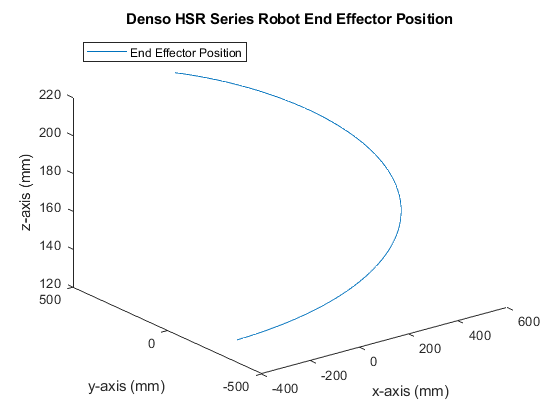

plot3(x_effector,y_effector,z_effector);
title('Denso HSR Series Robot End Effector Position')
xlabel('x-axis (mm)')
ylabel('y-axis (mm)')
zlabel('z-axis (mm)')
legend('End Effector Position', 'Location',"northwest")

## Discussion:

### Problem Set II-1:

It was shown that it is possible to define composite rotations by multiplicative relationships between rotational matricies. The order of multiplication these matricies determines whether a rotation is about the fixed frame's (aka the base frame or world frame) axes or the current frame's axes.

The sequence of multiplication was both symbolically described and numerically computed. In the numerical case, we were asked to use random values for the rotation angles. The built-in random number generator in MATLAB, `rng` was used to obtain random values and scale and offset them appropriately for radian angle values, as shown in the documentation example code for the MATLAB random number generator. As I defined the range to be from 0 to $2\pi$, the additive offset value $a$ was not necessary at it was set to 0 but was left in for completeness. I favored using the random number generator over other possible methods as it is built-in and using it offered a learning experience and greater familiarity with MATLAB.

To convince myself that the random numbers were being mapped correctly to the defined radian range, I computed the max and min of the randomly generated numbers after scale and offset to confirm that they were in fact between 0 and $2\pi$ radians. 

The resulting individual numerically-computed rotation matricies seem to perform the resulting rotations, at least mathematically. Further work could be done to plot the rotation sequences for a point or points to graphically illustrate the transformations occurring with each successive rotation.

### **Problem Set II-2:**

All coordinate frames were sucessfully descibed with respect to the base coordinate system by way of homogeneous transformation matricies. The numerical result is satisfying. The origins of coordinate frames 1, 2 and 3 relative to the base coordinate frame agree with the dimensional definitions in the figure presented with the problem. There is a -1 in the z column of the homogeneous matrix $H_3^2$ indicating a sign change of the z unit vector so that $z_3$ is at (0,0,-1) in the frame 0 coordinate system.There is also a "1" term in the 1st row, 2nd column and a "1" term in the 2nd row, 1st column, indicating a change in direction of the x and y unit vectors.  Unit vector $x_3$is at (0,1,0) in the frame 0 coordinate system and likewise unit vector $y_3$ is at (1,0,0) in the frame 0 coordinate system, which agrees with how the figure presents the orientation of the camera's coordinate frame. 

An assumption was made about the position of the 2nd coordinate frame that was not expicitly stated in the Materials and Methods section. That is, center of the cube was taken to mean the literal center of the cube at 0.1m in z relative to the table coordinate frame 1. The drawing is ambiguous as to if the center of the cube is defined as being coplanar with the table or 0.1mm above the table. The scale of the drawing in meters is not fine enough to determine where exactly the cube center is located.  In either case, the math works; either definition of the coordinate frame should not effect the ultimate homogeneous transform $H_3^0$ as long as $H_2^1$ and $H_3^2$ are consistent in how they relate frames.  

The choice of how to rotate coordinate frame 3 relative to coordinate frame 2 required some significant thought. I chose to rotate first by the z-axis in 90 degrees and then rotate by the current x-axis by 180 to make the z unit vector negative and place the new y-coordinate frame unit vector onto the world x-axis and vise versa. There are other ways to do this (i.e. first rotate in y by 180 degrees then rotate clockwise about the current z by 90 degrees)  but I chose the sequence demonstrated as it made the most intuitive sense to me. 

### Problem Set II-3:

The Denso HSR series robot was successfully analyzed and modeled in MATLAB. To do this, the Denso HSR robot's specifications were identified in the Denso catalog provided. From these specifications, the relevant robot parameters (link length, number and type of joints, etc) were identified or assumed and a simplified model of the robot describing its coordinate frames and the movement of its joints was established.

The assumptions made were regarding the centers of the two rotational joints. In both cases, an average of 2 heights was taken whose result looked to at least approximate the joint centers. As in Problem Set II-2, the location of the coordinate frames, for the purposes of this problem, needs only to be consistent when defining the homogeneous equations to relate matricies. We are concerned mainly with the location of the end-effector, which was well defined by the catalog drawing. 

Much time and thought was spent on how best to represent this. My approach was to define the relationships of coordinate frames of the 2 rotational joints with homgeneous matricies that have not only translational components but also a rotation about z component with a variable angle (i.e. $\phi ,\theta$). For the 3rd coordinate frame at the end of the prismatic joint I  subtracted variable $\Delta$ to capture changes in z-stroke. In the drawing, these variables are all equal to 0 and there is no rotation nor z-stroke. I included a commented out code snippet in the Results section to test any combination of variables if needed for a sanity-check. 

By defining each component homogeneous transform in this way, it is easy to vary the value of each joint angle or z-stroke distance. A `linspace` representation of the 180 steps from 0 to -180 degrees (clockwise rotation about the z-axis of the first joint) and 0 to -90 degrees (clockwise rotation about the z-axis of the second joint) and 0 to 100mm (0 to 100mm of downard z-stroke for each variable yields a collection of 180 coordinates that, when plotted successively, shows the position of the end-effector through the 180 step sequence. 

Each component H ($\left.H_1^0 ,H_2^1 ,H_3^2 \right)$ can be calculated in a 180-iteration loop, the composite homogeneous matrix created by multiplying the component H's together and the composite matrix $H_3^0$ made to act upon the (0,0,0) coordinate of frame 3 (the tip of the end effector) to translate the end effector point to the position indicated by the transformation. The x,y and z coordinates of the position of the end-effector relative to the base frame can then be collected in separate arrays for easy plottng using `plot3` in MATLAB.

When plotted, the end result is a curve that starts at (0,480,220) in terms of the base frame and ends at (-275,-205,120). The result is convincing. It is ultimately a clockwise translation from the start point to the end point, as required. Furthermore, The start position represents a position where both links are on the same y-axis unit vector for a total reach of 480mm and the end effector is 220mm in the z-axis from the base. At the end point, the length of the first link, 205mm, is present in the negative y-axis direction, indicating a 180 degree rotation about the first joint and the distance of -275mm in x is indicative of a rotation of the second link by 90 degrees clockwise when also taking into account the position of the first link as mentioned prior. The end position in z is 100mm less than the starting position, indicating 100mm of stroke distance has been travelled. 

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 35-74) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- [MATLAB rng function documentation](https://www.mathworks.com/help/matlab/ref/rng.html)

- [MATLAB rand function documentation](https://www.mathworks.com/help/matlab/ref/rand.html)

- [Denso Robot Catalog (For HSR Specs)](https://dc-docs.dcatalog.com/Densocompany/Robotics/72c75621-8544-41b4-9afa-a7f60153efbd/DENSO_Robotics_Catalog_D2277470.pdf?v=16000223827980.19439691676377646)